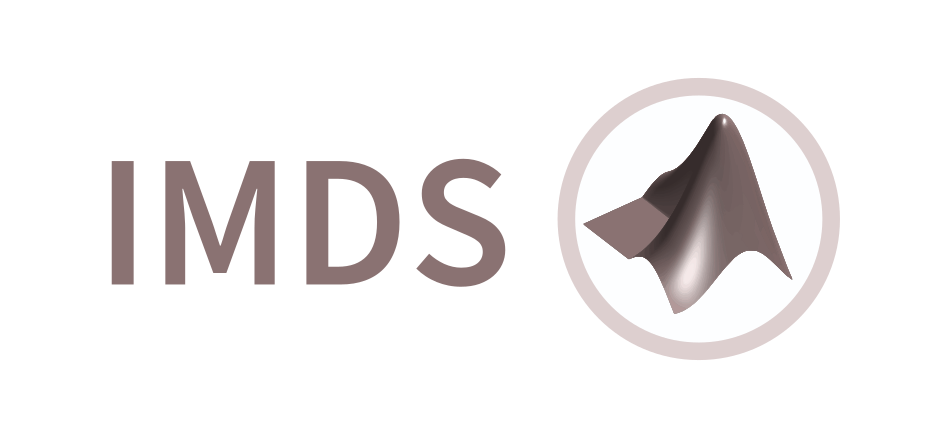

           Copyright (c) 2021-2022 Fabien Baillon.

This file is part of **IMDS**.

***IMDS**** is free software: you can redistribute it and/or modify it under the terms of the GNU General Public License as published by the Free Software Foundation, either version 3 of the License, or any later version.*

*Also see the file "License.mlx".*

# IMDS: Example codes of call functions for IMDS

## Getting started

The IMDS package facilitates working with image Datastore.

From Matlab, you can access to the IMDS documentation by the command:

doc("doc_IMDS/")

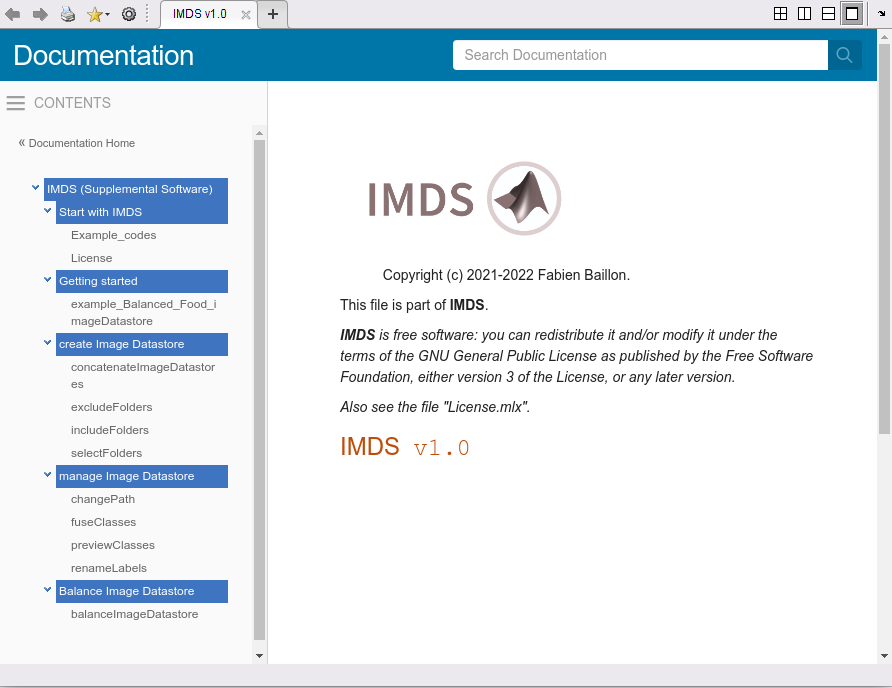

## Create Image Datastore

####     concatenateImageDatastores

Concatenate existing Image Datastores

imds = IMDS.concatenateImageDatastore(imds1, imds2, imds3, imds4);

or via a cell of image datastores

cellOfIMDS = {imds1, imds2, imds3, imds4};
imds = IMDS.concatenateImageDatastore(cellOfIMDS);

####     excludeFolders

Exclude some folders present in the `rootFolder` used to create the Image Datastore

rootFolder = "/path/to/the/root/folder/";
FoldersToExclude = ["Folder1", "Folder2"];
imds = IMDS.excludeFolders(rootFolder, FoldersToExclude);

####     includeFolders

Include some folders present in the `rootFolder` used to create the Image Datastore. The folder name will be use to label the class, by default.

rootFolder = "/path/to/the/root/folder/";
FoldersToInclude = ["Folder1", "Folder2"];
imds = IMDS.includeFolders(rootFolder, FoldersToInclude);

the same example, but with specifying the labels to rename the classes

rootFolder = "/path/to/the/root/folder/";
FoldersToInclude = ["Folder1", "Folder2"];
labelsNames = ["First Folder", "Second Folder"];
imds = IMDS.includeFolders(rootFolder, FoldersToInclude, labelsNames);

####     selectFolders

This function is a low-level function, which in fact hides behind the user functions `excludeFolders` and `includeFolders`. 

rootFolder = "/path/to/the/root/folder/";
FoldersToInclude = ["Folder1", "Folder2"];
flagExclusion = false;
labelsNames = ["First Folder", "Second Folder"];
imds = IMDS.selectFolders(rootFolder, FoldersToInclude, flagExclusion, labelsNames);

## Manage Image Datastore

####     changePath

This function changes the internal paths of the datastore. This is useful if you are moving images, but do not want to create the `imageDatastore` again.

old_rootFolder = "/old/path/to/the/root/folder/";
new_rootFolder = "/new/path/to/the/root/folder/";
IMDS.changePath(imds, old_rootFolder, new_rootFolder);

####     fuseClasses

This fonction merges all the imageDatastore classes, and a label is defined for the resulting class:

 imds_F = IMDS.fuseClasses(imds, "label_Class");

we can specify the final number of images in the created class

IMDS.fuseClasses(imds, "label_Class", 100);

####     previewClasses

Display a default preview of all classes:

IMDS.previewClassesIMDS(imds);

or display a preview of 4 images per class, for all classes whose label contains the string "`labelsContainThis`"

IMDS.previewClassesIMDS(imds, 4, labelsContainThis);

####     renameLabels

Rename Labels of an Image Datastore

old_Labels = ["label_1", "label_2"];
new_Labels = ["First label", "Second label"];
IMDS.renameLabels(imds, old_Labels, new_Labels);

## Balance Image Datastore

####     balanceImageDatastore

Balance the classes of the imageDatastore, so that each class has 1000 images 

IMDS.balanceImageDatastore(imds, 1000);

%#ok<*NASGU>
%#ok<*ASGLU> 